# LoRa transmission

## generate LoRa signal

 %  https://github.com/rpp0/gr-lora
 %  https://github.com/bhomssi/LoRaMatlab
 % TX
 % in:  message      payload message
 %         Bandwidth    signal bandwidth of LoRa transmisson  
 %         SF           spreading factor
 %         Pt           transmit power in deicbels
 %         Fs           sampling frequency
 %         dF           frequency offset
 %         varargin{1}  code rate
 %         varargin{2}  symbols in preamble
 %         varargin{3}  sync key
 % 
 %   out:  signal       LoRa IQ waveform
 %         packet       encoded message

 %Rx
  % in:  signal       payload message
  %        Bandwidth    signal bandwidth of LoRa transmisson  
  %        SF           spreading factor
  %        Coherence    (1) coherent or (2) non-coherent FSK Detection
  %        Fs           sampling frequency
  %        dF           carrier frequency shift
  %        varagin{1}   SNR
  %        varagin{2}   Preamble Symbol number
  % 
  %  out:  message       LoRa payload message chahracters
  %        symbols_Demod LoRa payload symbols vector  
clear;
SF=12;
BW=125e3

BW = 125000

Pt=22;%dBm
Fs=3*BW;%freq?
%message=randi([0 (2^SF)-1 ],10,1)
message = char(randi([32 126], 1, 10)) % Generate a random string of length 10

message = '9,>w#D!@^6'

signal=LoRa_Tx(message,BW,SF,Pt,Fs,0);

## signal

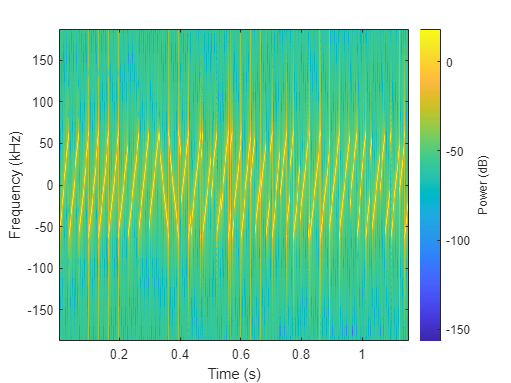

windowSize=2^10;%2^14 for small windows to show individual advertisements, 2^20 for larger windows to show overall activity
window=hamming(windowSize);
overlap=windowSize/2;
nfft=2^14;%same as for windowsize
centerfreq=868e6;
spectrogram(signal, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs

## apply doppler

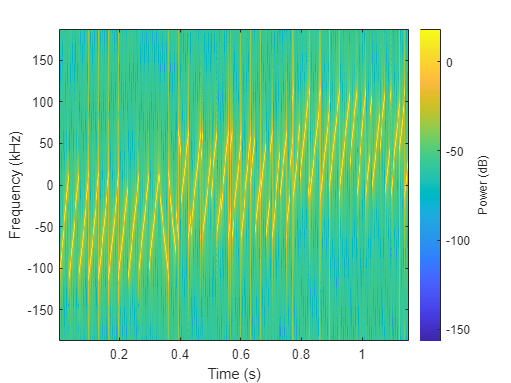

maxshift=50e3;
% Get the number of IQ samples
num_samples = length(signal);
%static doppler shift of 10kHz
for i=1:num_samples
    doppler_shift(i)=0;
    if i<=num_samples/3
        doppler_shift(i)=-maxshift;
    elseif i>=num_samples*2/3
            doppler_shift(i)=maxshift;
    end
end
% Generate time vector
t = (0:num_samples-1) / Fs;

% Apply Doppler shift to IQ samples
for i = 1:num_samples
    phase_shift = 2 * pi * doppler_shift(i) * t(i);
    dopplerSignal(i) = signal(i) * exp(1j * phase_shift);
end
spectrogram(dopplerSignal, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs

## demod


ogMessage=LoRa_Rx(signal,BW,SF,1,Fs,0);
char(ogMessage)

ans = '9,>w#D!@^6'

## demod doppler


dopplerMessage=LoRa_Rx(signal,BW,SF,1,Fs,0)

dopplerMessage =     57    44    62   119    35    68    33    64    94    54


char(dopplerMessage)

ans = '9,>w#D!@^6'

## errors?


errorrate=sum(message~=ogMessage)/length(message)

errorrate = 0

dopplerErrorrate=sum(message~=dopplerMessage)/length(message)

dopplerErrorrate = 0